# Import data from MET Office Weather Data

Script for importing data from the following text file:

Auto-generated by MATLAB on 12-Sep-2020 12:16:44

## Aufgabe 1:

Importieren Sie den Datensatz*** MET Office Weather Data.csv*** in Matlab. Gehen Sie wie folgt vor:

- Speichern Sie die Datei lokal auf ihrem Rechner

- Öffnen Sie die Datei über den Button ***Browse for folder***

- Erzeugen Sie ein Skript für das Lesen des Datensatzes und speichern Sie dieses Skript ab.

- Dazu müssen Sie den Button ***Import Data*** verwenden.

- Studieren Sie das Skript und ändern Sie den Namen der Matlab-Variablen, welche durch den Import erzeugt wird in ***weatherD***.

- Welche Matlab Funktion wird verwendet, um die daten einzulesen?

### Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 8);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["year", "month", "tmax", "tmin", "af", "rain", "sun", "station"];
opts.VariableTypes = ["int16", "int8", "double", "double", "categorical", "double", "double", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["af", "station"], "EmptyFieldRule", "auto");

% Import the data
weatherD = readtable("C:\Users\Ioannis\OneDrive\HFIE\PA_P1\Wetterstation\MET Office Weather Data.csv", opts);

## **Aufgabe 2:**

Führen Sie das erstellt Skript aus. Dadurch wird die Variable weatherD mit dem Typ Table erzeugt. Führen Sie den Befehl summary aus. Welche Informationen von Summary sind nicht hilfreich?

summary(weatherD)

Variables:

    year: 37049×1 int16

        Values:

            Min            0  
            Median      1976  
            Max         2020  

    month: 37049×1 int8

        Values:

            Min           0   
            Median        6   
            Max          12   

    tmax: 37049×1 double

        Values:

            Min             -0.9  
            Median          12.4  
            Max             28.3  
            NumMissing      1619  

    tmin: 37049×1 double

        Values:

            Min             -8.6  
            Median          5.5   
            Max             17    
            NumMissing      1542  

    af: 37049×1 categorical

        Values:

            0      16897  
            1       2425  
            10       703  
            11       663  
            12       571  
            13       499  
            14       415  
            15       367  
 

## **Aufgabe 3:**

Ergänzen Sie ihr Skript so, dass eine neue Variable wDfixed erzeugt wird, die nur noch gültigen Werte enthält. Wie viele Zeilen wurden aus der Tabelle entfernt?

% Hier wird eine neue Variable erzeugt, welche nur gültige Werte enthält.
wDfixed = rmmissing(weatherD); 

% Hier wird die Anzahl der entfernten Zeilen ausgegeben.
numRemoved = height(weatherD) - height(wDfixed);

## Aufgabe 4:

Erweitern Sie ihr Skript so, dass ihre Tabelle nach Jahr und Monat sortiert wird und erstellen Sie einen plot, welcher die Maximal-Temperatur über die Jahre anzeigt. Weshalb ist das Ergebnis nicht sinnvoll?

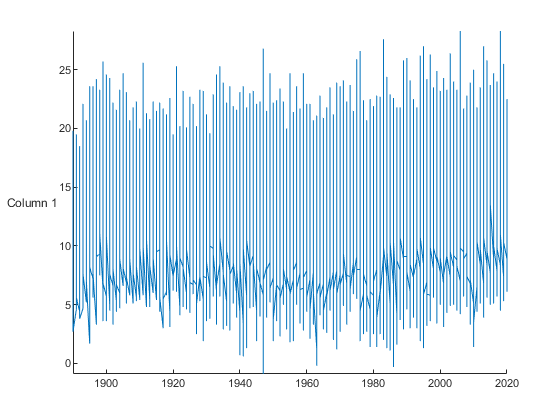

% Die Tabelle wird nach Jahr und Monat sortiert.
SortedTable = sortrows(wDfixed, {'year','month'},'ascend');

% Hier wird die Maimxal-Temperatur über die Jahre angezeigt.
stackedplot(SortedTable.year, SortedTable.tmax)

## Aufgabe 5:

Welche Wetterstation liefert die meisten Daten? Erstellen Sie eine neue Tabelle, welche ausschliesslich die Daten dieser Wetterstation beinhaltet.

Stations = categories(SortedTable.station);
NumStations = countcats(SortedTable.station);
[~,TmaxIndex] = max(NumStations);
MaxStation = Stations{TmaxIndex};
MaxStationData = SortedTable(SortedTable.station == MaxStation,:);

## Aufgabe 6:

Erstellen Sie eine neue Tabelle, welche die durchschnittlichen Temperaturen pro Jahr enthält. Verwenden Sie die Funktion ***groupsummary(..)*** und stellen Sie die durchschnittlichen Maximal-Temperaturen seit Messbeginn in einem Plot dar. Verwenden Sie die Funktion*** 'mean'*** für die Berechnung.

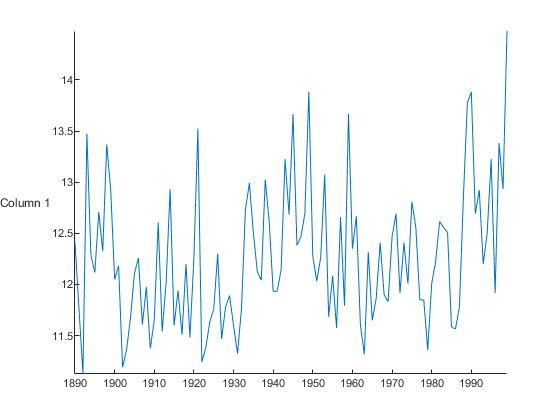

Mean_Tmax = groupsummary(MaxStationData,'year','mean','tmax');
stackedplot(Mean_Tmax.year, Mean_Tmax.mean_tmax); 

## Aufgabe 7:

Führen Sie dieselbe Auswertung nochmals durch. Verwenden Sie diesmal aber die Funktion 'median' und zeichnen Sie den Verlauf in derselben Grafik auf. Wählen Sie einen geeigneten Markierer, um die zwei Datenreihen zu unterscheiden.

Vergleichen Sie die Daten und kommentieren Sie, Entspricht die Grafik ihren Erwartungen?

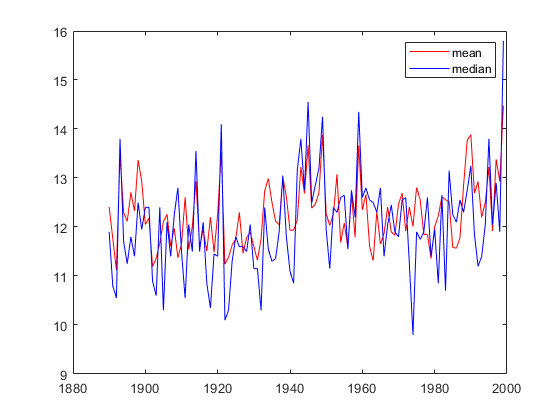

% ToDo: Insert in the same table from exercise 6 the median values 
Median_Tmax = groupsummary(MaxStationData,'year','median','tmax');
plot(Mean_Tmax.year, Mean_Tmax.mean_tmax, 'r')
hold on
plot(Median_Tmax.year, Median_Tmax.median_tmax, 'b')
legend('mean','median')
hold off

## Aufgabe 8:

Welches ist die Messstation mit der grössten mittleren Regenmenge pro Jahr, und welches ist die Messstation mit der kleinsten mittleren Regenmenge pro Jahr.

Max_Rain_old = 0; Min_Rain_old = 0;

for k = 1:(length(Stations))
    Data = SortedTable(SortedTable.station == Stations{k},:);
    Mean_Rain = groupsummary(Data,'year','mean','rain');
    RainMax = max(Mean_Rain.mean_rain);
    RainMin = min(Mean_Rain.mean_rain);
    if Max_Rain_old < RainMax
        Max_Rain_old = RainMax;
        MaxRainStation = Stations{k};
    end
    if k == 1 || Min_Rain_old > RainMin
        Min_Rain_old = RainMin;
        MinRainStation = Stations{k};
    end
end

## Aufgabe 9:

Zeichnen Sie eine Scatterplot, welcher die Regenmenge und die Temperatur einer Messstation gegenüberstellt. Beschriften Sie das Diagramm mit Titel, X-Achse und Y-Achse.

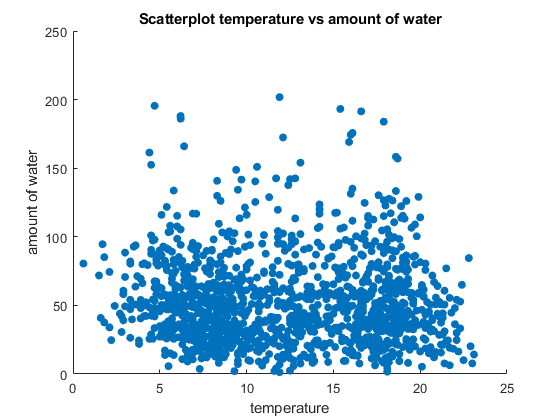

scatter(MaxStationData.tmax, MaxStationData.rain, 'filled');
title('Scatterplot temperature vs amount of water')
ylabel('amount of water')
xlabel('temperature')

## Aufgabe 10:

Vergleichen Sie die Maximal-Temperaturen dieser zwei Messstationen in einem Boxplot.

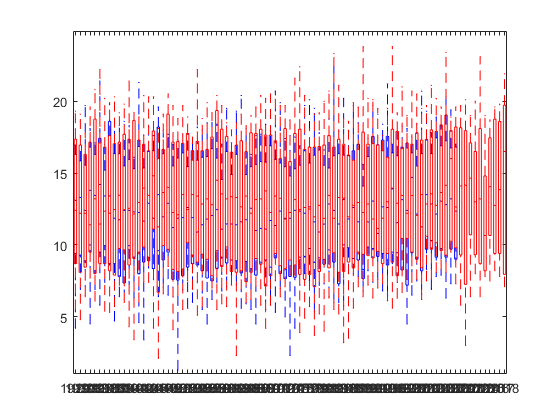

Station_1 = SortedTable(SortedTable.station == Stations{1},:);
boxplot(Station_1.tmax, Station_1.year, 'Colors', 'b')
hold on
Station_2 = SortedTable(SortedTable.station == Stations{2},:);
boxplot(Station_2.tmax, Station_2.year, 'Colors', 'r')
hold off

## Clear temporary variables

clear opts